# Set uniform water depths

This guide explains how to use Matlab to quickly set the model bathymetry to a uniform depth

## Initialise the bathymetry object

Get the bathymetry object, as shown in previous guides.

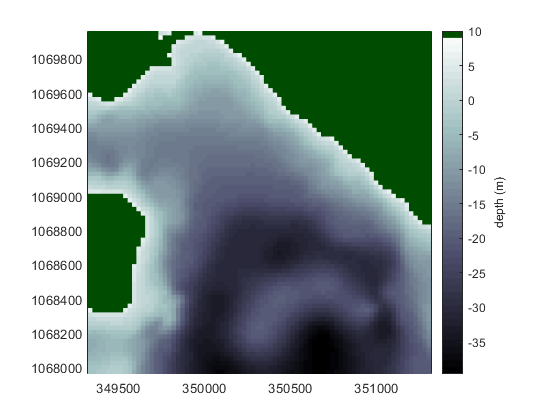

projectDir = 'C:\newdepomod_projects\bay_of_fish';
project    = NewDepomod.Project.create(projectDir);
bathy      = project.bathymetry;

bathy.plot

## Edit the water depth data

In order to edit *only the seabed values *we nned to obtain their indexes. These can be identified as follows:

idxs = bathy.seabedIndexes

idxs = 79×79 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   0   0   0   0   0   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0 

We next set the data table values for all of these indexes to a single uniform value. Let's say we want the bathymetry to be a uniform 20 m...

bathy.data(idxs) = -20;

Now, let's take a look

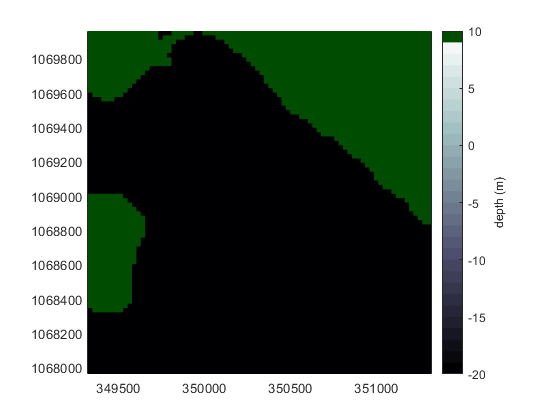

figure; bathy.plot

## Saving the altered information back to file

These changes can be easily written back to the original file using

bathy.toFile

or

bathy.toFile('path\to\file.depomodbathymetryproperties')

if the changes should be saved to a different file.